clear all

load 1gTruth.mat
g1 = gTruth.DataSource;
tabletrain1  = objectDetectorTrainingData(gTruth,'SamplingFactor',1);
clear gTruth

load 2gTruth.mat
g2 = gTruth.DataSource;
tabletrain2  = objectDetectorTrainingData(gTruth,'SamplingFactor',1);

tabletrain = [tabletrain1;tabletrain2];

rng(0)
shuffledIndices = randperm(height(tabletrain));
idx = floor(0.7 * height(tabletrain));

trainingIdx = 1:idx;
trainingDataTbl = tabletrain(shuffledIndices(trainingIdx),:);

validationIdx = idx+1 : idx + 1 + floor(0.1 * length(shuffledIndices) );
validationDataTbl = tabletrain(shuffledIndices(validationIdx),:);

testIdx = validationIdx(end)+1 : length(shuffledIndices);
testDataTbl = tabletrain(shuffledIndices(testIdx),:);

imdsTrain = imageDatastore(trainingDataTbl{:,'imageFilename'});
bldsTrain = boxLabelDatastore(trainingDataTbl(:,2:8));

imdsValidation = imageDatastore(validationDataTbl{:,'imageFilename'});
bldsValidation = boxLabelDatastore(validationDataTbl(:,2:8));

imdsTest = imageDatastore(testDataTbl{:,'imageFilename'});
bldsTest = boxLabelDatastore(testDataTbl(:,2:8));

trainingData = combine(imdsTrain,bldsTrain);
validationData = combine(imdsValidation,bldsValidation);
testData = combine(imdsTest,bldsTest);

augmentedTrainingData = transform(trainingData,@augmentData);

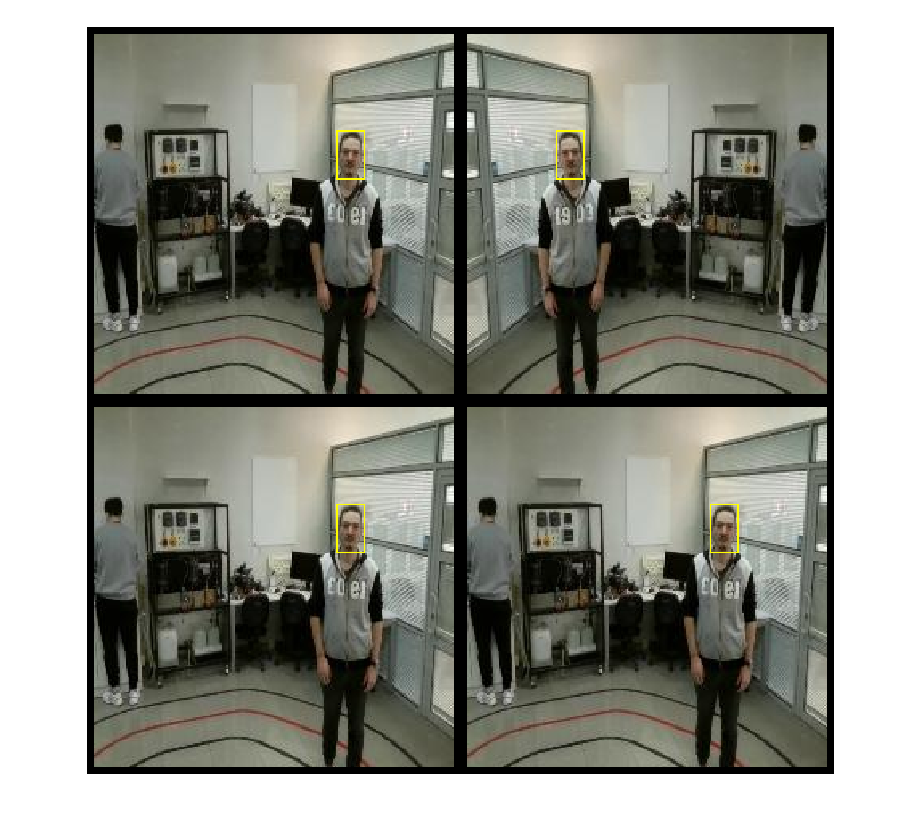

augmentedData = cell(4,1);
for k = 1:4
    data = read(augmentedTrainingData);
    augmentedData{k} = insertShape(data{1},'Rectangle',data{2});
    reset(augmentedTrainingData);
end
figure
montage(augmentedData,'BorderSize',10)